# Scitran project reporting

`Illustrates searching the Flywheel database from Matlab for subject`

`information in a particular project.  This code works for scitran`

`generally, though I prefer working with the Flywheel instance.`

BW/Scitran Team 2016

## Authorization

% Open the scitran object
st = scitran('scitran');

## Search for the subject information

% Find the sessions in the project
sessions = st.search('sessions',...
    'project label','SVIP Released Data (SIEMENS)');
length(sessions)

ans = 283

## Get the subject information

subjects = stSubjectInfo(sessions);
ages     = stSubjectGet(subjects,'age');

## Print out the sex distribution

sex = stSubjectGet(subjects,'sex');
unknownSexSessions = find(sex == 'u');
if isempty(unknownSexSessions)
    fprintf('\n---------\n');
    fprintf('Sex coded in all sessions\n');
    fprintf('---------\n');
else
    fprintf('\n---------\n');
    fprintf('Sessions with unknown subject sex:  %d\n',unknownSexSessions);
    fprintf('---------\n');
end


---------


Sex coded in all sessions


---------



nMale    = sum(sex=='m');
nFemale  = sum(sex =='f');
nUnknown = sum(sex == 'u');
fprintf('%d Males\n%d Females\n%d   Unknown\n',nMale,nFemale,nUnknown);

160 Males
123 Females
0   Unknown


## Summarize ages in a graph

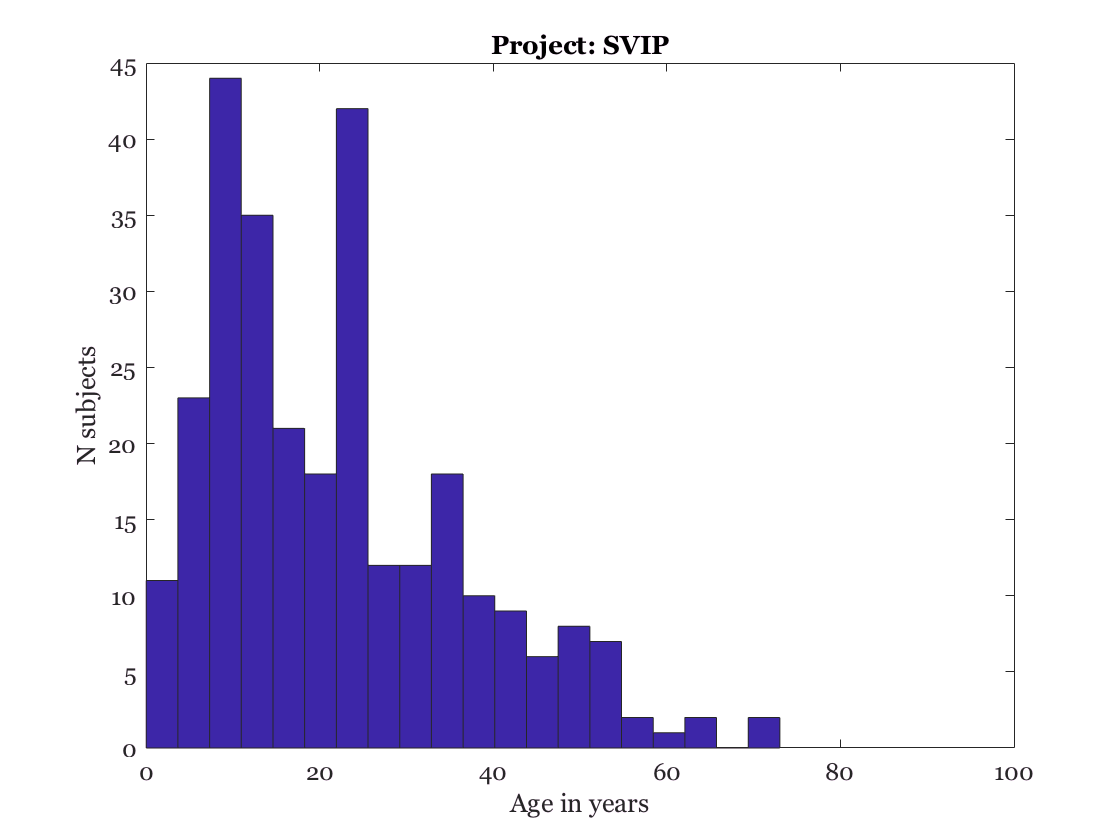

figure; hist(ages,20); 
xlabel('Age in years'); ylabel('N subjects');
set(gca,'xlim',[0 100]);
title(sprintf('Project: %s','SVIP'));